# **SVD and Best Low Rank Approximation **

## 1. Singular Value Decomposition

Let $$\mathbb{K}$$ denote $\mathbb{R}$ or $\mathbb{C}$, and let $A\in\mathbb{K}^{m{\times}n}$. Set $r=\text{rank}(A)$ for short. 

We state well-known facts. Set  $r=\text{rank}(A)$ for short. We state well-known facts.  

- 
$$\text{rank}({A^\ast}A) = \text{rank}(AA^\ast) = \text{rank}(A), \quad  {A^\ast}A \geq 0.$$


- There exist positive numbers $\sigma_1\geq\dots\geq\sigma_r>0$ such that $\det(zE_n-A) = z^{n-r}(z-\sigma_1)\cdots(z-\sigma_r).$

- There exist an orthonormal system $\{u_1,\dots,u_m\}$ of $\mathbb{K}^m$and an orthonormal system$\{v_1,\dots,v_n\}$  of $\mathbb{K}^n$ such that 


$$A=U{\Sigma}V^\ast=\sum_{l=1}^r\sigma_lu_lv_l^\ast, \quad U=[u_1,\dots,u_m], \quad V=[v_1,\dots,v_n], \quad \Sigma=\pmatrix{\sigma_1 &  & & \cr & \ddots & & \cr & & \sigma_r & \cr & & &}.$$


## 2. Best low rank approximation

Let $A\in\mathbb{K}^{m{\times}n}$. Set $r=\text{rank}(A)$ for short. Suppose that the SVD of $A$ is given by 


$$A=U{\Sigma}V^\ast=\sum_{l=1}^r\sigma_lu_lv_l^\ast.$$


Set 


$$A_k=U{\Sigma}V^\ast=\sum_{l=1}^k\sigma_lu_lv_l^\ast, \quad k=1,\ldots,r.$$


Then $\text{rank}(A_k)=k$. It is well-known that $A_k$ is the best approximation of $A$ among $m{\times}n$ matrices with rank $k$. 

More precisely we have the Eckart-Young inequality of the form

$||A-B|| \geq ||A-A_k||, 
\quad
B\in\mathbb{K}^{m{\times}n}, 
\quad
\text{rank}(B)=k$,

where  $||\cdot||$ is the spectral norm of matrices defined by 


$$||B||:=
\max_{x \in \mathbb{K}^n\setminus\{0\}}
\frac{|Bx|}{|x|},$$


and $|\cdot|$ is the standard norm of numeric vectors. 

The same inequlity holds if we replace the spectral norm by the Frobenius norm or the nuclear norm. 

% l. oad image file
RGB=imread('char_kway_teow.jpg');
[s1,s2,s3]=size(RGB);
R2=max(s1,s2);
RGB=imresize(RGB, 400/R2);
[R,G,B] = imsplit(RGB);
% imshow(RGB)
% whos R, whos G, whos B

DR=double(R);
DG=double(G);
DB=double(B);

for r=1:100
    [UR,SR,VR]=svds(DR,r);
    DRr=UR*SR*VR';
    Rr=uint8(DRr);
    [UG,SG,VG]=svds(DG,r);
    DGr=UG*SG*VG';
    Gr=uint8(DGr);
    [UB,SB,VB]=svds(DB,r);
    DBr=UB*SB*VB';
    Br=uint8(DBr);
    SVD(:,:,1,r)=(Rr);
    SVD(:,:,2,r)=(Gr);
    SVD(:,:,3,r)=(Br);
end

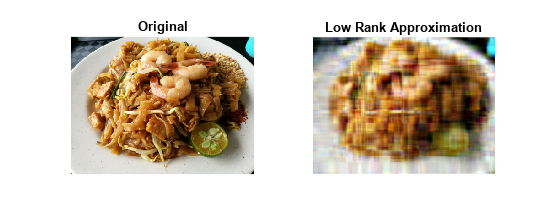

k =10;
subplot(1,2,1);
imshow(RGB);
title('Original');
subplot(1,2,2);
imshow(SVD(:,:,:,k));
title('Low Rank Approximation');
set(gcf,'Position',[600,200,1000,400]);
saveas(gcf,'svd.png');